clc;
clear;
close all;

% input pneumonia data 
[X_1, m1]=process_data("C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\PNEUMONIA",20,20,1);

Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\PNEUMONIA\person1000_bacteria_2931.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\PNEUMONIA\person1000_virus_1681.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\PNEUMONIA\person1001_bacteria_2932.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\PNEUMONIA\person1002_bacteria_2933.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\PNEUMONIA\person1003_bacteria_2934.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\PNEUMONIA\person1003_virus_1685.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\PNE

ans =         1731         400


y1=ones(m1,1);
x11=size(y1)

x11 =         1731           1


x1=length(y1)

x1 = 1731

% input normal data 
[X_2, m2]=process_data("C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\NORMAL",20,20,1);

Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\NORMAL\IM-0559-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\NORMAL\IM-0560-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\NORMAL\IM-0561-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\NORMAL\IM-0562-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\NORMAL\IM-0563-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\NORMAL\IM-0564-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\NORMAL\IM-0565-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignmen

ans =    956   400


y2=zeros(m2,1)

y2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x22=size(y2)

x22 =    956     1


x2=length(y2)

x2 = 956

% merging both data
training_data=[X_1;
               X_2];
y=[y1; y2];
x3=size(y)

x3 =         2687           1


x33=length(y)

x33 = 2687

x4=size(training_data)

x4 =         2687         400


x44=length(training_data)

x44 = 2687


X=training_data;

%% ============ Part 2: Compute Cost and Gradient ============

%  Setup the data matrix appropriately, and add ones for the intercept term
[m, n] = size(X);

% Add intercept term to x and X_test
X = [ones(m, 1) X];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

lambda = 2000;

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 5000);

% Optimize
[theta, cost, exit_flag] = ...
	fminunc(@(t)(lrCostFunction(t, X, y, lambda)), initial_theta, options);


Solver stopped prematurely.

fminunc stopped because it exceeded the iteration limit,
options.MaxIterations = 4.000000e+02.





% Print theta to screen
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.055575



fprintf('theta:%f \n',theta);

theta:-0.000083 
theta:-0.006711 
theta:0.023377 
theta:-0.003964 
theta:-0.019784 
theta:0.004809 
theta:0.015656 
theta:-0.000580 
theta:-0.002147 
theta:0.029202 
theta:-0.001661 
theta:-0.026133 
theta:0.006516 
theta:-0.007598 
theta:0.011710 
theta:0.004724 
theta:0.002698 
theta:0.007117 
theta:-0.003645 
theta:-0.016503 
theta:0.007195 
theta:-0.010678 
theta:0.007437 
theta:0.032483 
theta:-0.014442 
theta:-0.015830 
theta:-0.007666 
theta:0.001921 
theta:0.007578 
theta:0.006110 
theta:0.003232 
theta:-0.016224 
theta:-0.016667 
theta:-0.019144 
theta:-0.004129 
theta:0.008357 
theta:0.010715 
theta:0.006380 
theta:0.004510 
theta:-0.013595 
theta:0.016825 
theta:0.010554 
theta:-0.016869 
theta:0.013309 
theta:-0.009268 
theta:-0.012029 
theta:-0.005833 
theta:0.009630 
theta:0.000679 
theta:-0.004949 
theta:-0.004694 
theta:-0.021666 
theta:0.001515 
theta:0.002030 
theta:0.017189 
theta:-0.010561 
theta:0.003341 
theta:-0.001606 
theta:-0.012159 
theta:-0.003278 
theta:0.0

%% input pneumonia cross validation data 
[X_CV_1, m_CV_1]=process_data("C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\p",20,20,1);

Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\p\person100_virus_184.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\p\person101_virus_187.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\p\person101_virus_188.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\p\person102_virus_189.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\p\person103_virus_190.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\p\person104_virus_191.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\p\person105_virus_192.jpeg
Now reading C:\Users

ans =    542   400


y_CV_1 = ones(m_CV_1,1);
% input normal cross validation data 
[X_CV_2, m_CV_2]=process_data("C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\n",20,20,1);

Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\n\IM-0115-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\n\IM-0117-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\n\IM-0119-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\n\IM-0122-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\n\IM-0125-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\n\IM-0127-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\train\val\n\IM-0128-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\

ans =    393   400


y_CV_2 = zeros(m_CV_2,1);
X_CV = [X_CV_1;X_CV_2];
y_CV = [y_CV_1;y_CV_2];
X_CV = [ones(length(y_CV), 1) X_CV];

% ploting lambda vs training and cross validation 
[All_lambda, error_train, error_CV] = validationCurve(X, y, X_CV, y_CV);


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

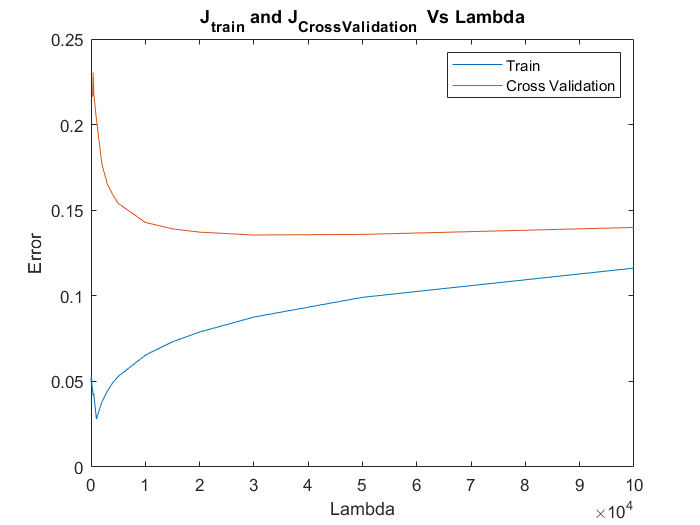

plot(All_lambda, error_train, All_lambda, error_CV);
legend('Train', 'Cross Validation');
xlabel('Lambda');
ylabel('Error');

title('J_t_r_a_i_n_ and J_C_r_o_s_s_V_a_l_i_d_a_t_i_o_n_  Vs Lambda')

for i = 1:length(All_lambda)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
   
    fprintf('%f\t%f\t%f\n',All_lambda(i), error_train(i), error_CV(i));
end

lambda		Train Error	Validation Error


0.000000	0.049571	NaN
1.000000	0.049608	NaN
10.000000	0.051258	NaN
50.000000	0.053249	NaN
100.000000	0.053034	NaN
200.000000	0.046826	0.216483
300.000000	0.045071	0.216561
400.000000	0.041700	0.230425
500.000000	0.043030	0.218365
1000.000000	0.028021	0.203045
2000.000000	0.037997	0.177145
3000.000000	0.044238	0.165311
4000.000000	0.049210	0.159160
5000.000000	0.052915	0.154008
10000.000000	0.065299	0.142865
15000.000000	0.073143	0.139104
20000.000000	0.078850	0.137182
30000.000000	0.087576	0.135505
50000.000000	0.099109	0.135865
100000.000000	0.116186	0.139925


% input pneumonia test data 
[test_data_1 ,s1]=process_data("C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\PNEUMONIA",20,20,1)

Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\PNEUMONIA\person100_bacteria_475.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\PNEUMONIA\person100_bacteria_477.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\PNEUMONIA\person100_bacteria_478.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\PNEUMONIA\person100_bacteria_479.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\PNEUMONIA\person100_bacteria_480.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\PNEUMONIA\person100_bacteria_481.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\PNEUMONIA\person

ans =    390   400


test_data_1 =     30    25    15     8     4     2     0     0     0    22    33     0     0     0     0     0     0     0     0     0    70    51    44    30    19    14    11    12    17    26    35    42    44    37    48    48    49    54    57    56    84    77    72    67    62    73    90   109   130   149
   107    33    35    48    61    53    44    41    36    27    15    16    17    18    17    18    16    16    17    19    78    62    63    62    47    41    36    26    16     4     6     8     9    11    14    19    25    31    37    43    42    55    61    46    45    45    46    45    41    44
   163   133   123   133   161   174   170   176   179   176   173   183   181   171   149   121   103    83    57    35   162   104    70    92   124   117   106   106   104    85    74    68    49    28    17    12    12    13    16    20    61    65    80   105   117    92    76    66    51    25
    49    64    87   104    90    65    52    49    42    36    27    14     7     

s1 = 390

% h1=imresize(img,[20 20]);
% h2=reshape(h1,1,20*20*3);
 test_data_2=[ones(s1,1) test_data_1]

test_data_2 =      1    30    25    15     8     4     2     0     0     0    22    33     0     0     0     0     0     0     0     0     0    70    51    44    30    19    14    11    12    17    26    35    42    44    37    48    48    49    54    57    56    84    77    72    67    62    73    90   109   130
     1   107    33    35    48    61    53    44    41    36    27    15    16    17    18    17    18    16    16    17    19    78    62    63    62    47    41    36    26    16     4     6     8     9    11    14    19    25    31    37    43    42    55    61    46    45    45    46    45    41
     1   163   133   123   133   161   174   170   176   179   176   173   183   181   171   149   121   103    83    57    35   162   104    70    92   124   117   106   106   104    85    74    68    49    28    17    12    12    13    16    20    61    65    80   105   117    92    76    66    51
     1    49    64    87   104    90    65    52    49    42    36    27    14     

 for i=1:1:s1
 m1(i)=predict(theta,test_data_2(i,:));
 end

% input normal test data 
 [test_data_3 ,s2]=process_data("C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\NORMAL",20,20,1)

Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\NORMAL\IM-0001-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\NORMAL\IM-0003-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\NORMAL\IM-0005-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\NORMAL\IM-0006-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\NORMAL\IM-0007-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\NORMAL\IM-0009-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\A2 Logistic Regression\chest_xray\test\NORMAL\IM-0010-0001.jpeg
Now reading C:\Users\alokp\OneDrive\Documents\MATLAB\Assignments CLG\

ans =    234   400


test_data_3 =     30    28    29    88   123   134   136   138   140   131   102    72    53    31    31    31    30    29    28    28    27    18    61   141   153   174   175   164   152   157   136    62    43    32    24    21    21    22    23    24    24    20    92   147   169   181   188   183   175   173
    53    40    30    36    73    35    33    34    34    36    37    37    38    38    38    39    39    39    39    39   144   134   107    75    59    56    53    52    51    48    45    44    42    41    39    35    33    33    32    32   183   174   161   151   138   133   132   133   138   147
    29    54   139   176   187   187   170   157   147    88    56    38    30    26    26    27    28    28    28    28    36    78   134   185   189   165   161   172   183   137   120   115   102    82    58    39    28    21    19    19    34    85   139   164   167   156   166   180   195   196
    88   113   115   129   143   145   146   152   146   121   118   125   125   12

s2 = 234


 test_data_4=[ones(s2,1) test_data_3]

test_data_4 =      1    30    28    29    88   123   134   136   138   140   131   102    72    53    31    31    31    30    29    28    28    27    18    61   141   153   174   175   164   152   157   136    62    43    32    24    21    21    22    23    24    24    20    92   147   169   181   188   183   175
     1    53    40    30    36    73    35    33    34    34    36    37    37    38    38    38    39    39    39    39    39   144   134   107    75    59    56    53    52    51    48    45    44    42    41    39    35    33    33    32    32   183   174   161   151   138   133   132   133   138
     1    29    54   139   176   187   187   170   157   147    88    56    38    30    26    26    27    28    28    28    28    36    78   134   185   189   165   161   172   183   137   120   115   102    82    58    39    28    21    19    19    34    85   139   164   167   156   166   180   195
     1    88   113   115   129   143   145   146   152   146   121   118   125   12

 for i=1:1:s2
 m2(i)=predict(theta,test_data_4(i,:));
 end
real_ans= zeros(s2,1);
acc = mean(double((m2') == real_ans))*100;
fprintf('normal percentage:%f \n',acc);

normal percentage:39.316239 


real_ans2= ones(s1,1);
acc2 = mean(double((m1') == real_ans2))*100;
fprintf('pneumonia percentage:%f\n',acc2);

pneumonia percentage:97.435897


 
 disp(sum(m1)),disp(sum(m2));

   380

   142



% confusion matrix
trueVal = [real_ans;
            real_ans2];
predVal = [m2';
           m1'];
[cm,order] = confusionmat(trueVal,predVal)

cm =     92   142
    10   380


order =      0
     1


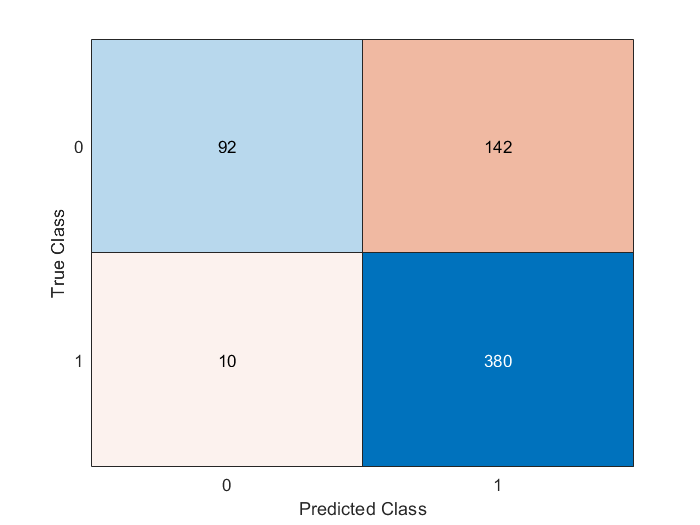

figure
cmat = confusionchart(cm,order);

TP = cm(2,2);
FP = cm(1,2);
FN = cm(2,1);
TN = cm(1,1);
accuracy = (TP+FN)/(TP+FP+TN+FN);
disp(accuracy);

    0.6250



% precision
% out of all people having neumonia
precision = TP/(TP+FP);
disp(precision);

    0.7280



% recall
% how muc we predicted correctly
recall = TP/(TP+FN);
disp(recall);

    0.9744



% F1 score
F1 = 2*(precision*recall/(precision+recall));
disp(F1);

    0.8333



[lambda_arr,F1_arr_train,F1_arr_CV] = F1_VS_Lambda(X,y,X_CV,y_CV);


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

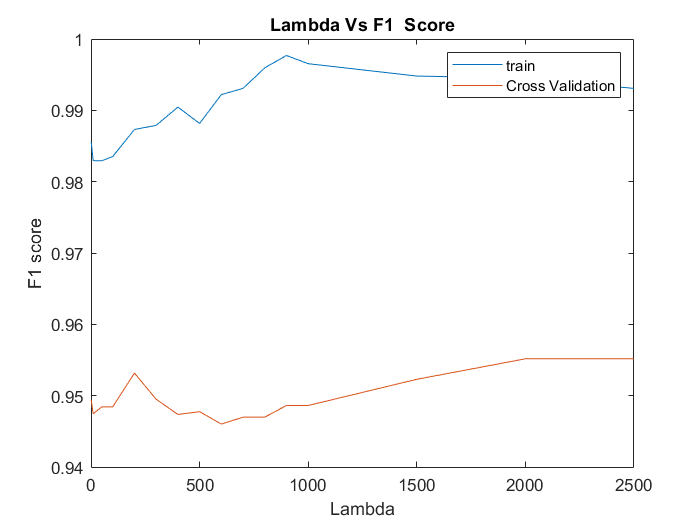

plot(lambda_arr,F1_arr_train,lambda_arr,F1_arr_CV);
legend("train","Cross Validation");

title('Lambda Vs F1  Score')
xlabel('Lambda')
ylabel('F1 score')

% Optimal Lambda taken
fprintf('lambda\t %f',2000);

lambda	 2000.000000